# Deploy Real-Time YOLOv9 Object Detection on NVIDIA Jetson AGX Orin using Simulink

This example shows how to deploy a Simulink® model on the NVIDIA® Jetson AGX Orin™ board for real-time object detection using an IP camera stream. This example detects and tracks objects in real-time by using the advanced YOLOv9 deep learning network. The Simulink model in the example uses the network stream input and display blocks from the MATLAB® Coder™ Support Package for NVIDIA Jetson and NVIDIA DRIVE™ Platforms to capture the live video stream from an IP camera, process it using TensorRT™ optimized CUDA® code, and display the bounding boxes and prediction results on a monitor connected to the Jetson platform.

This example specifically uses an NVIDIA Jetson AGX Orin Developer Kit.

**Prerequisites**

*Target Board Requirements*

- NVIDIA Jetson AGX Orin embedded platform.

- Ethernet cable to connect the target board and host PC (or network connection for the IP camera).

- An IP Camera accessible over the network (RTSP/HTTP stream).

- A monitor connected to the display port of the target.

- GStreamer libraries on the target for IP stream decoding.

- NVIDIA CUDA® toolkit and driver on the target.

- NVIDIA cuDNN and TensorRT™ libraries on the target for high-performance inference.

- Environment variables on the target for the compilers and libraries. For more information, see Prerequisites for Generating Code for NVIDIA Board.

*Development Host Requirements*

- Environment variables for the compilers and libraries. For more information, see Third-Party Hardware (GPU Coder) and Setting Up the Prerequisite Products (GPU Coder).

## Connect to NVIDIA Jetson

The support package uses an SSH connection over TCP/IP to execute commands while building and running the generated CUDA code on the Jetson platforms. Connect the target platform to the same network as the host computer.

To communicate with the NVIDIA hardware, create a live hardware connection object by using the [jetson](docid:nvidia_ref#mw_1b5b766b-73ab-473c-9639-be639d71968d) function.

To communicate with the NVIDIA hardware, create a live hardware connection object by using the `jetson` function. When connecting to the target board for the first time, provide the IP address, user name, and password of the target board.

hwobj = jetson;

### Checking for CUDA availability on the target...
### Checking for 'nvcc' in the target system path...
### Checking for cuDNN library availability on the target...
### Checking for TensorRT library availability on the target...
### Checking for prerequisite libraries is complete.
### Gathering hardware details...
### Checking for third-party library availability on the target...
### Gathering hardware details is complete.
Board name              : NVIDIA Jetson AGX Orin Developer Kit
CUDA Version            : 11.4
cuDNN Version           : 8.6
TensorRT Version        : 8.5
GStreamer Version       : 1.16.3
V4L2 Version            : 1.18.0-2build1
SDL Version             : 1.2
OpenCV Version          : 4.5.4
Available Webcams       : USB 2.0 Camera: USB Camera
Available GPUs          : Orin
Available Digital Pins  : 7  11  12  13  15  16  18  19  21  22  23  24  26  29  31  32  33  35  36  37  38  40


When you create a hardware object, the software performs hardware and software checks, installs the MATLAB IO server on the target board, and gathers information. To choose a hardware board for performing a remote build, use the `setupCodegenContext()` method.

## Verify GPU Environment on Target Board

To verify that the compilers and libraries necessary for running this example are set up correctly, use the `coder.checkGpuInstall` function. Since this example utilizes TensorRT for optimized inference, set the deep learning target library to `tensorrt`.

envCfg = coder.gpuEnvConfig('jetson');
envCfg.DeepLibTarget = 'tensorrt';
envCfg.DeepCodegen = 1;
envCfg.HardwareObject = hwobj;
coder.checkGpuInstall(envCfg);

Compatible GPU           : PASSED 
CUDA Environment         : PASSED 
	Runtime   : PASSED 
	cuFFT     : PASSED 
	cuSOLVER  : PASSED 
	cuBLAS    : PASSED 
cuDNN Environment        : PASSED (Warning: Deep learning code generation has been tested with cuDNN v8.9. The provided cuDNN library v8.6 may not be fully compatible.)
TensorRT Environment     : PASSED (Warning: Deep learning code generation has been tested with TensorRT v8.6. The provided TensorRT library v8.5 may not be fully compatible.)
Deep Learning (TensorRT) Code Generation: PASSED 
TensorRT FP32 Compute Capability Check: PASSED 


## Simulink Model for Real-Time YOLOv9 Detection

The Simulink model for object detection contains a deep learning block to predict bounding boxes and labels, a video source block to capture the live IP camera stream, and a display block to visualize the results. Additional processing operations are implemented to format the image data and annotate the output.

open_system('yolov9_orin_ipcam_detect');

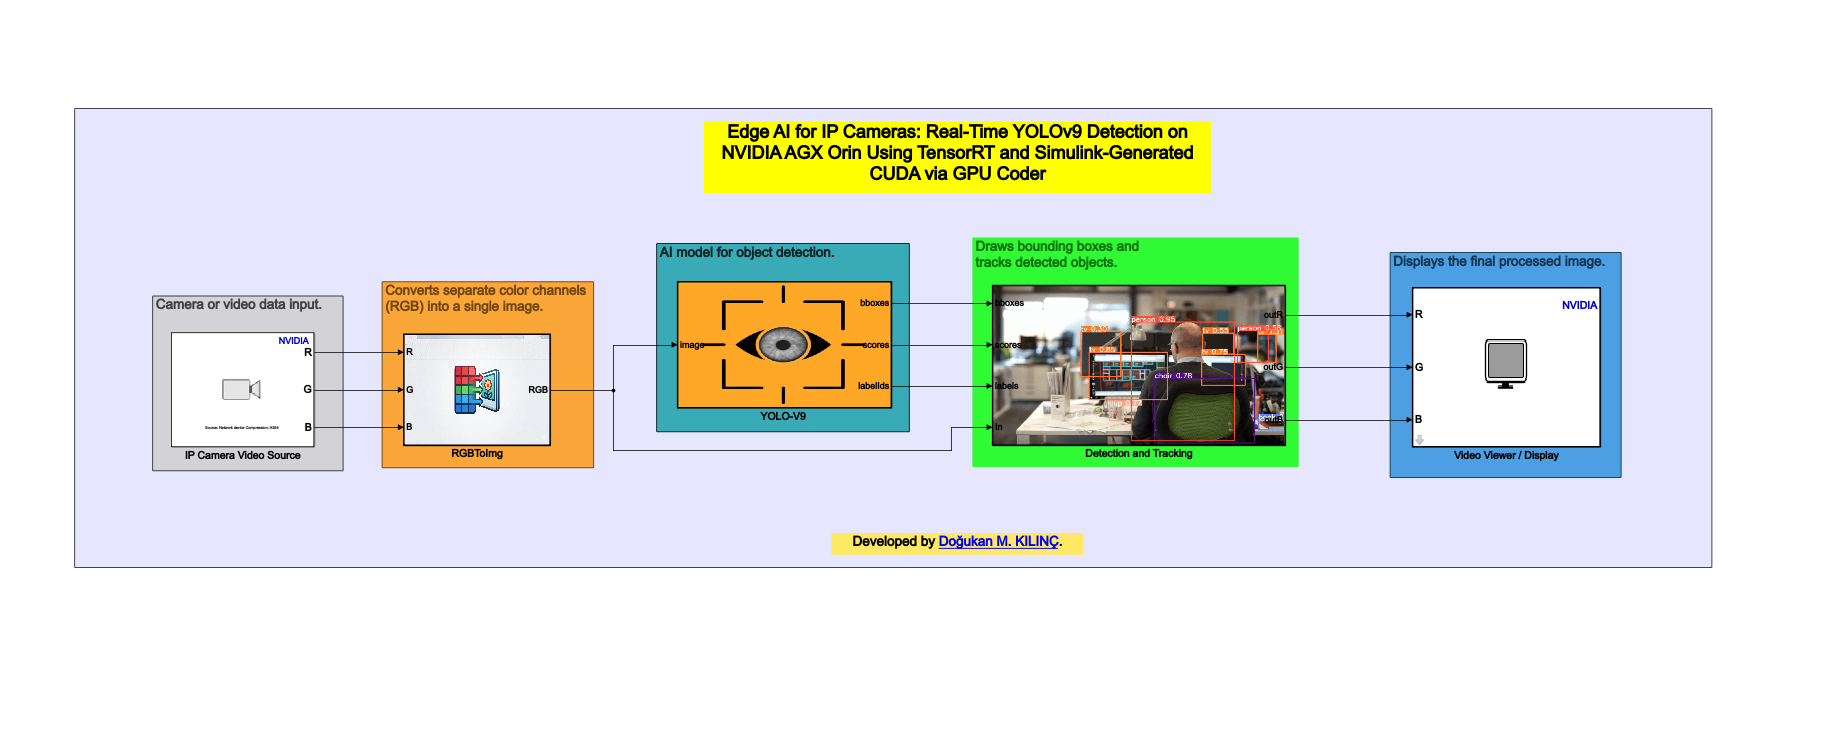

The model is divided into five main stages:

- **NVIDIA Video Source:** Unlike standard USB webcams, this block is configured to receive an RTSP/HTTP video stream from an IP camera over the network. It extracts the raw R, G, and B color channels for each time-step.

- **RGBToImg:** This subsystem converts the separate R, G, and B component outputs from the video source into a planar RGB image format required by the object detection network.

- **YOLO-V9 (Detection Model):** This block takes the image frame and runs prediction using the YOLOv9 deep learning network. To achieve real-time performance on the AGX Orin, this block is optimized using NVIDIA TensorRT. The output contains bounding box coordinates (`bboxes`), confidence scores (`scores`), and class labels (`labelIds`).

- **Detection and Tracking:** This processing block calculates the frames per second (FPS), tracks objects across frames, and annotates the input image with the prediction labels, their corresponding scores, and bounding boxes.

- **Video Viewer / Display:** The resulting output image is provided to the NVIDIA Display block, which opens an SDL display window showing the final annotated video stream on the monitor connected to the Jetson target.

## Configure the Model for Simulation and Deployment

To generate CUDA code, the model must be enabled with specific code generation settings. The model in this example is preconfigured to generate optimized C++ CUDA code for the NVIDIA Jetson platform.

**1. Hardware Implementation Settings**To configure the connection to your specific target board:

- Open the **Configuration Parameters** dialog box and select the **Hardware Implementation** pane.

- Ensure the **Hardware board** is set to `NVIDIA Jetson`.

- Under the **Target hardware resources** section, select **Board Parameters**.

- Enter the **Device Address** (e.g., `192.168.2.50`), **Username** (e.g., `dogukankilinc`), and **Password** of your NVIDIA Jetson AGX Orin target board.

           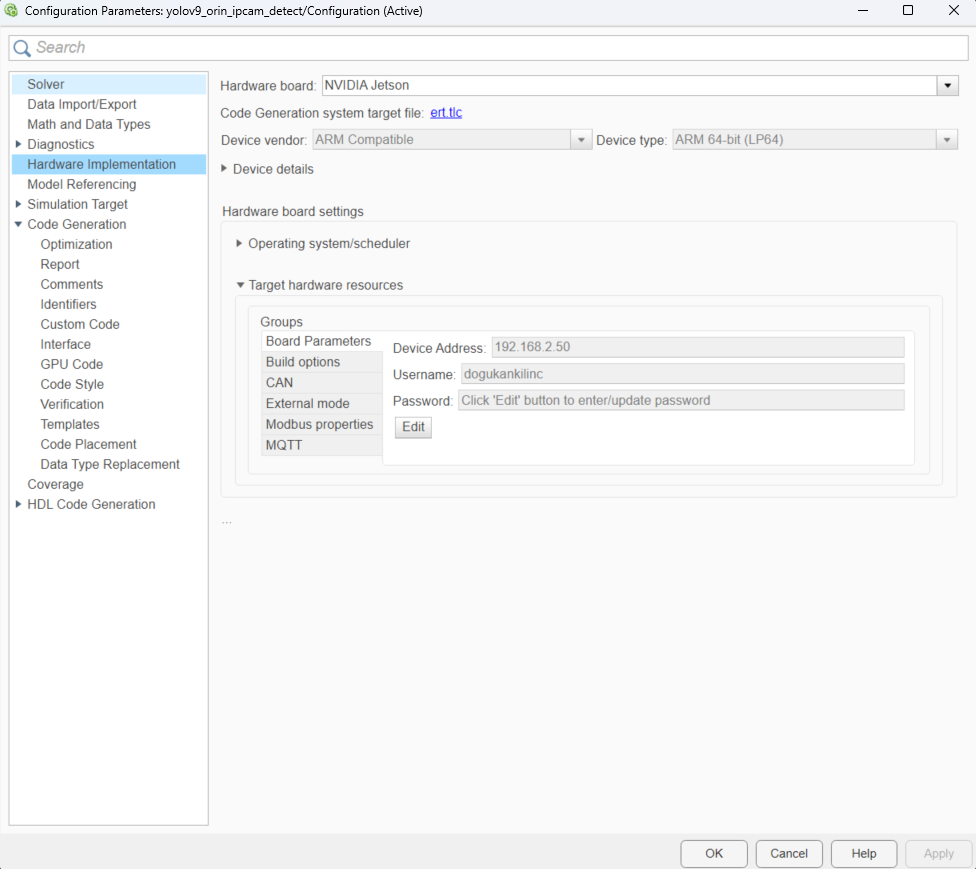    

## Deep Learning Target Library Configuration

Simulink allows you to generate code using different deep learning libraries depending on your performance requirements and target hardware.

- In the Configuration Parameters dialog box, navigate to **Code Generation > Interface**.

- Scroll down to the **Deep learning** section.

- For the **Deep learning library** parameter, you can choose between `None`, `cuDNN`, and `TensorRT`. Since we are targeting high-performance, real-time object detection on the AGX Orin, select `TensorRT`.

           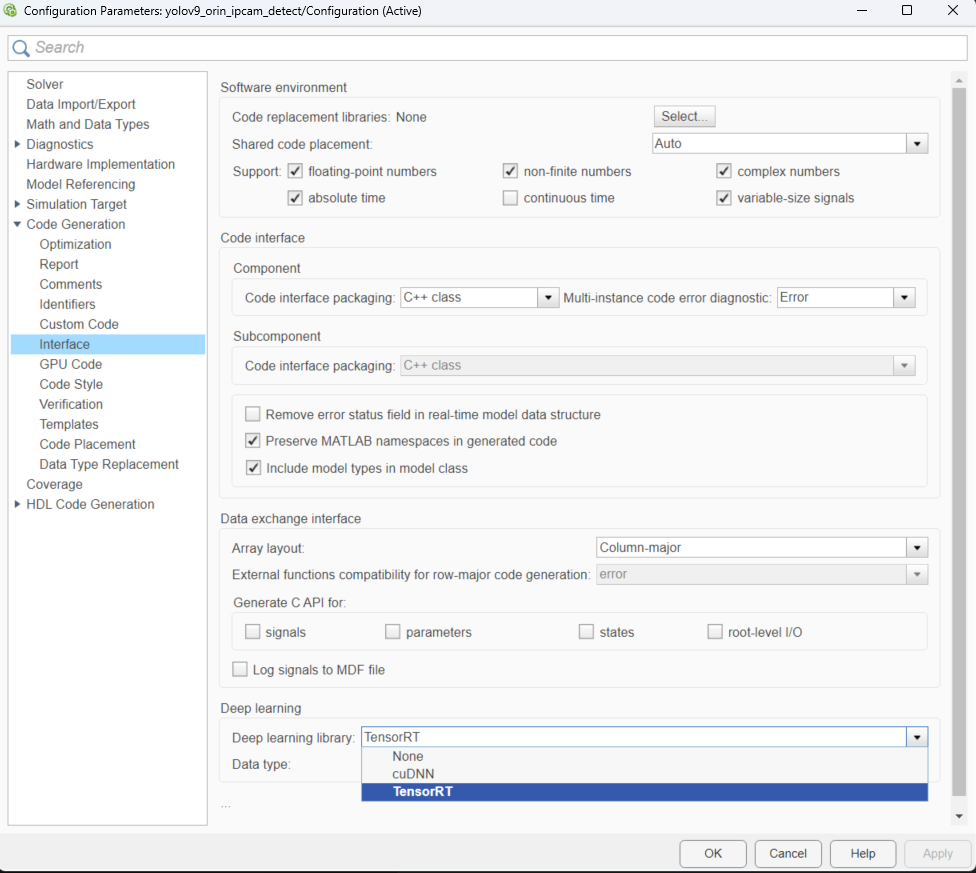

## Precision and Data Type Optimization (FP16)

When utilizing TensorRT, you have the advantage of optimizing the network's mathematical precision to accelerate inference speed.

- Still under the **Deep learning** section, locate the **Data type** dropdown menu.

- You have the option to generate code using either `fp32` (32-bit floating-point) or `fp16` (16-bit half-precision floating-point).

- For this example, we select `fp16`. Using fp16 precision takes full advantage of the Tensor Cores on the Jetson AGX Orin, significantly increasing the frames per second (FPS) for the YOLOv9 model with minimal impact on detection accuracy.

- Click **Apply** and **OK** to save your configuration.

           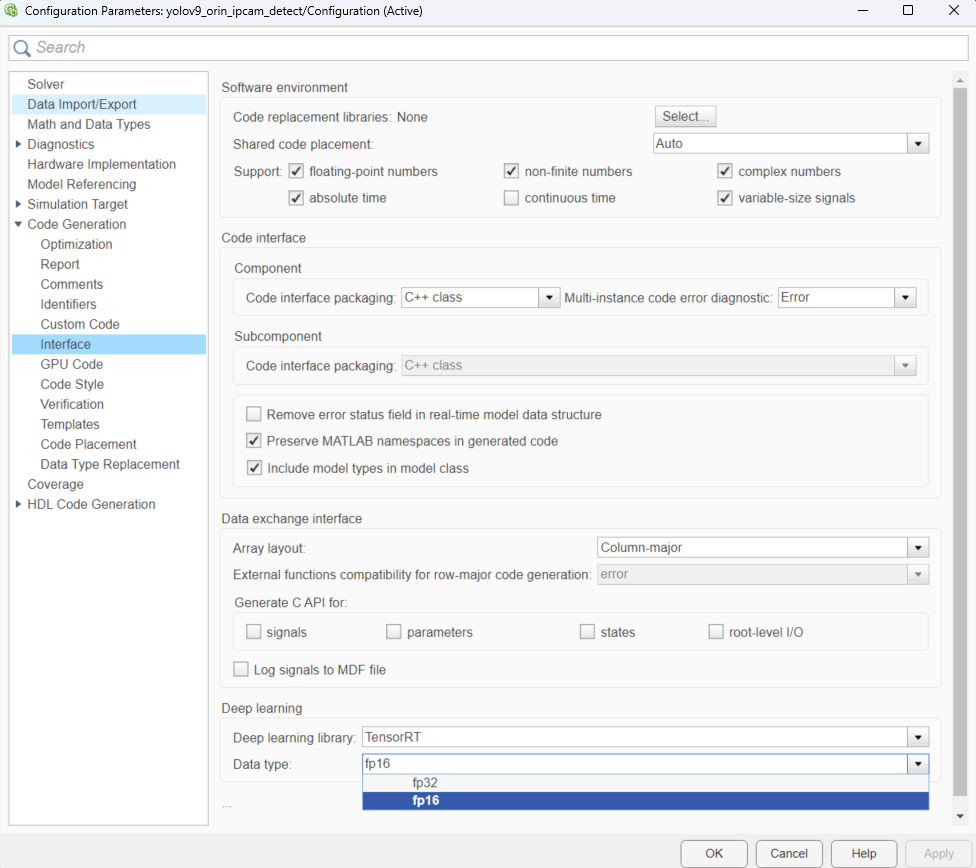

## Generate and Deploy Model on Target Board

- To generate CUDA code for the model, deploy the executable to the target, and run the application, open the **Hardware** tab on the Simulink Editor.

- Click **Build, Deploy & Start** to begin the process.

           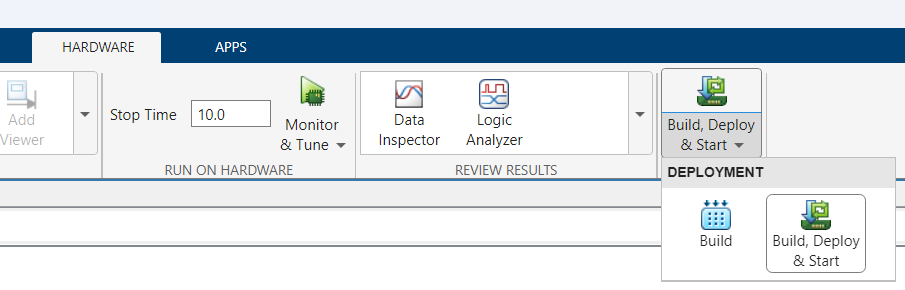     

*Note: Since the deep learning target library is set to TensorRT, the code generator will build a TensorRT engine specific to the YOLOv9 network and the AGX Orin hardware during the first deployment. This engine building process can take several minutes. Subsequent builds will reuse the generated engine and deploy much faster.*

## View Detection Results on the NVIDIA Jetson

When the application successfully starts on the target board, an SDL display window opens on the monitor connected to the Jetson AGX Orin.

This window will show the real-time video stream captured from the IP camera. The YOLOv9 network processes each frame, and the tracking subsystem draws bounding boxes around detected objects. You will see the class labels (e.g., person, chair, monitor), their corresponding confidence scores, and the real-time average FPS calculated by the system overlaid on the video stream.

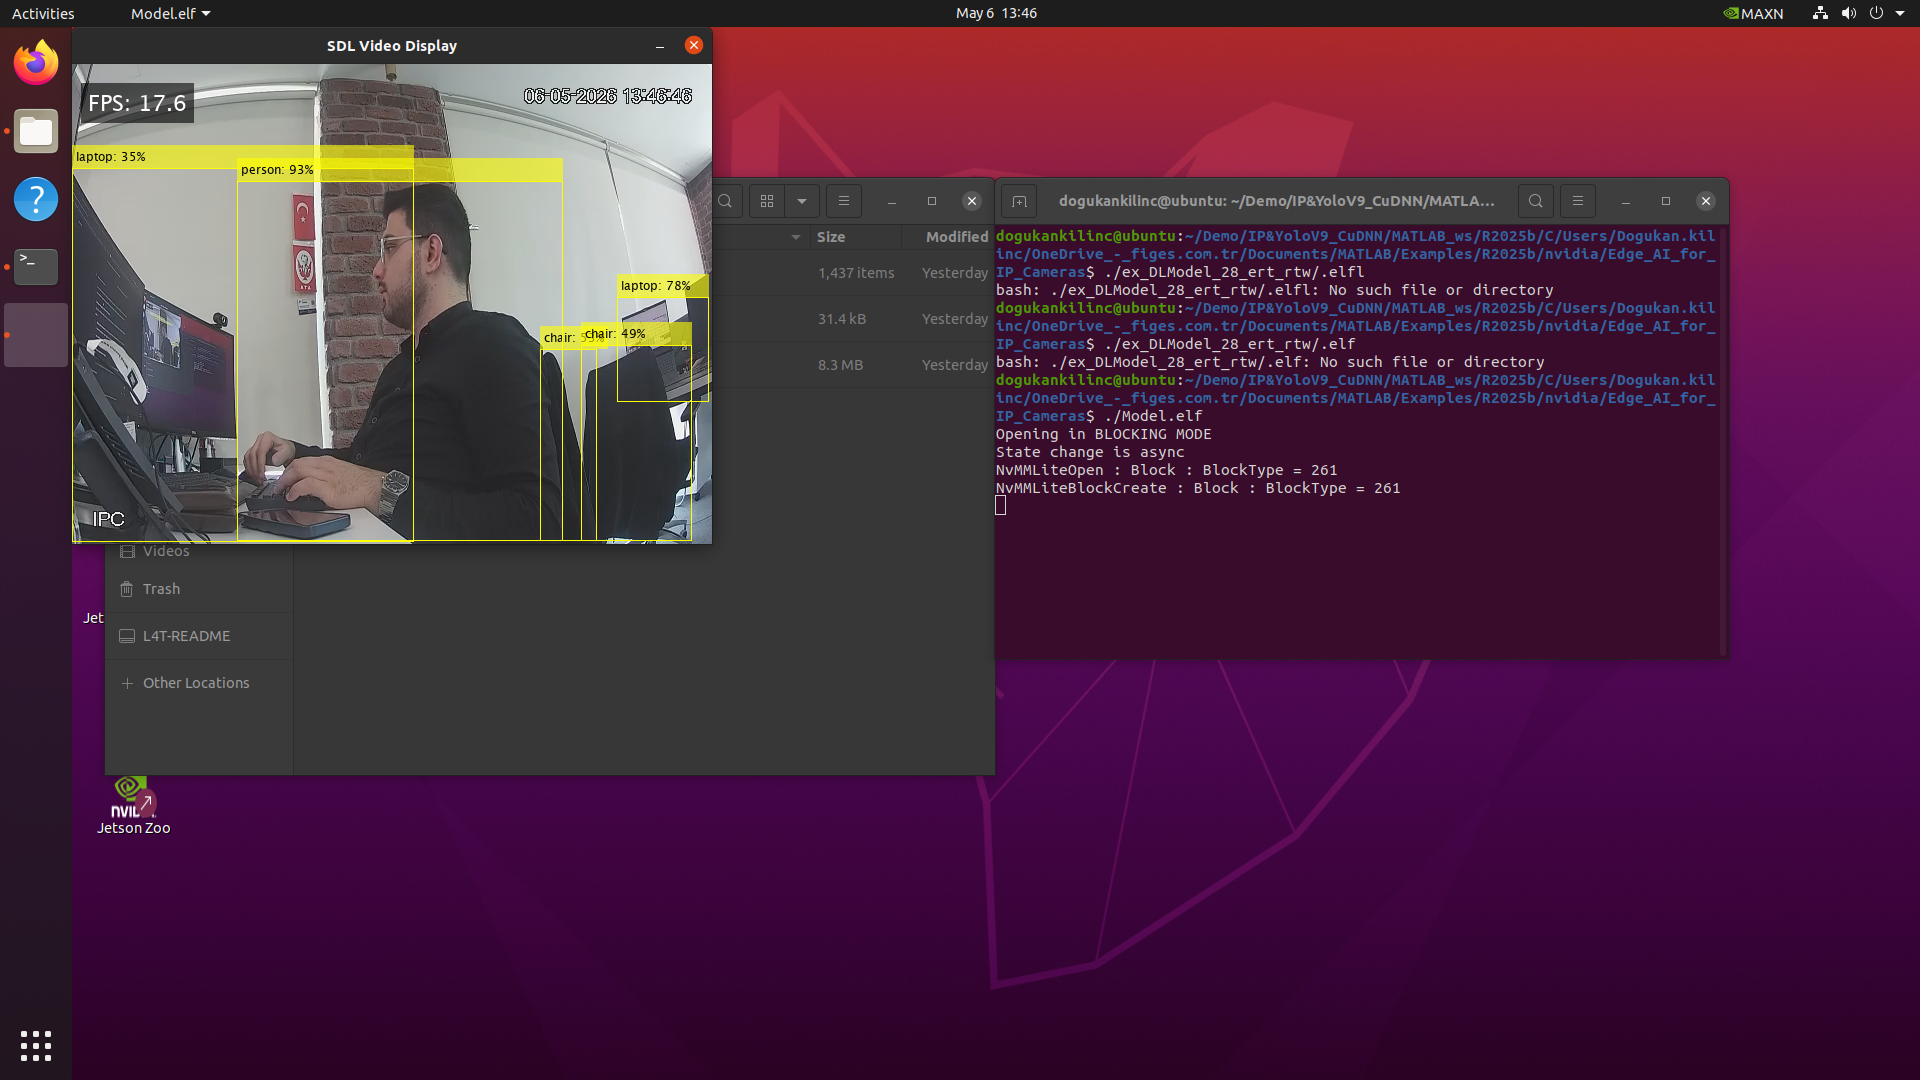

## Stop Application

To stop the running application on the target board from your host MATLAB environment, use the `stopModel` method of the hardware connection object.

stopModel(hwobj, 'yolov9_orin_ipcam_detect');

## Close Model

Run the `close_system` function to close the Simulink model without saving any unsaved workspace changes.

close_system('yolov9_orin_ipcam_detect', 0);

*Developed by *[*Doğukan M. KILINÇ*](https://www.linkedin.com/in/dgkilinc/)* | May 6, 2026*